Reproduce and explore Fig. 1. First, click run below to load everything needed for other sections to run.

 
clear
clf

% this line is at request of Steven for swim function
global data

load('../../all_data.mat','data')

load('real.mat','beat')
realBeat = beat;

load('synthetic.mat','beat')
syntheticBeat = beat;

cc = importdata('colormap.txt');
inds = 1 : 4 : 100;
cc = cc(inds,:);

addpath ../../../OpenScience_Walker_Computer-assisted_beat-pattern_analysis.nosync/

% find min and max of all y values in waveform, for purpose of ylim
allValues = [];
for i=1:216
    allValues = [allValues; data{i}.cartesian(:,:,2)];
end
waveformMiny = min(allValues,[],"all");
waveformMaxy = max(allValues,[],"all");



Fig. 1(a). Captured frame from a video of a spermatozoon.

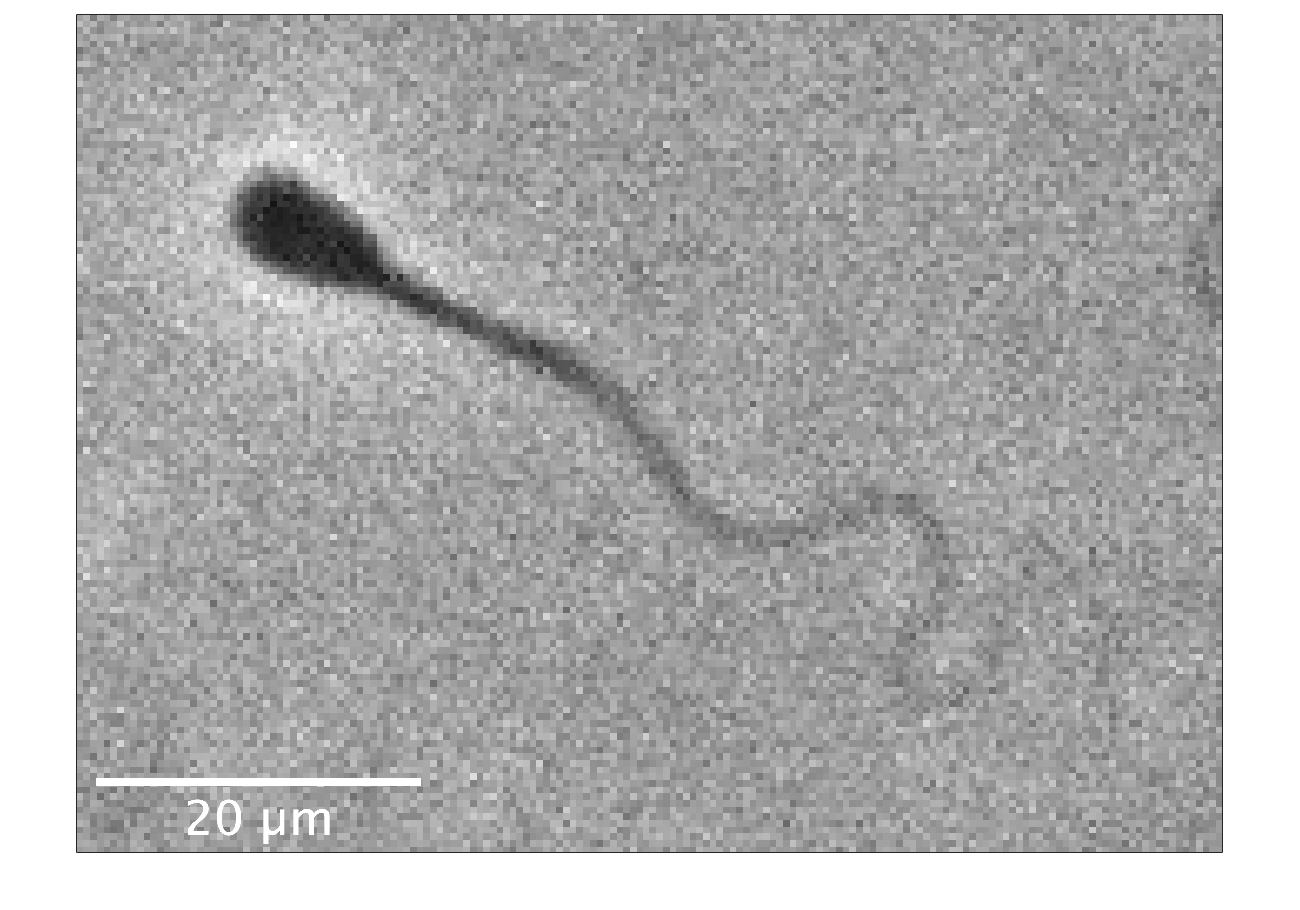

 
figure
imshow( imread('raw.tif') ,[0 255]);
axis on
set(gca,'XTick',[],'YTick',[])
box on

Fig. 1(b). Flagellum identified from the captured frame in Fig. 1(a), using automated methodology of Walker BJ, Ishimoto K, Wheeler RJ. 2019 Automated identification of flagella from videomicroscopy via the medial axis transform. Sci. Rep. 9, 5015. (doi:10.1038/s41598-019-41459-9).

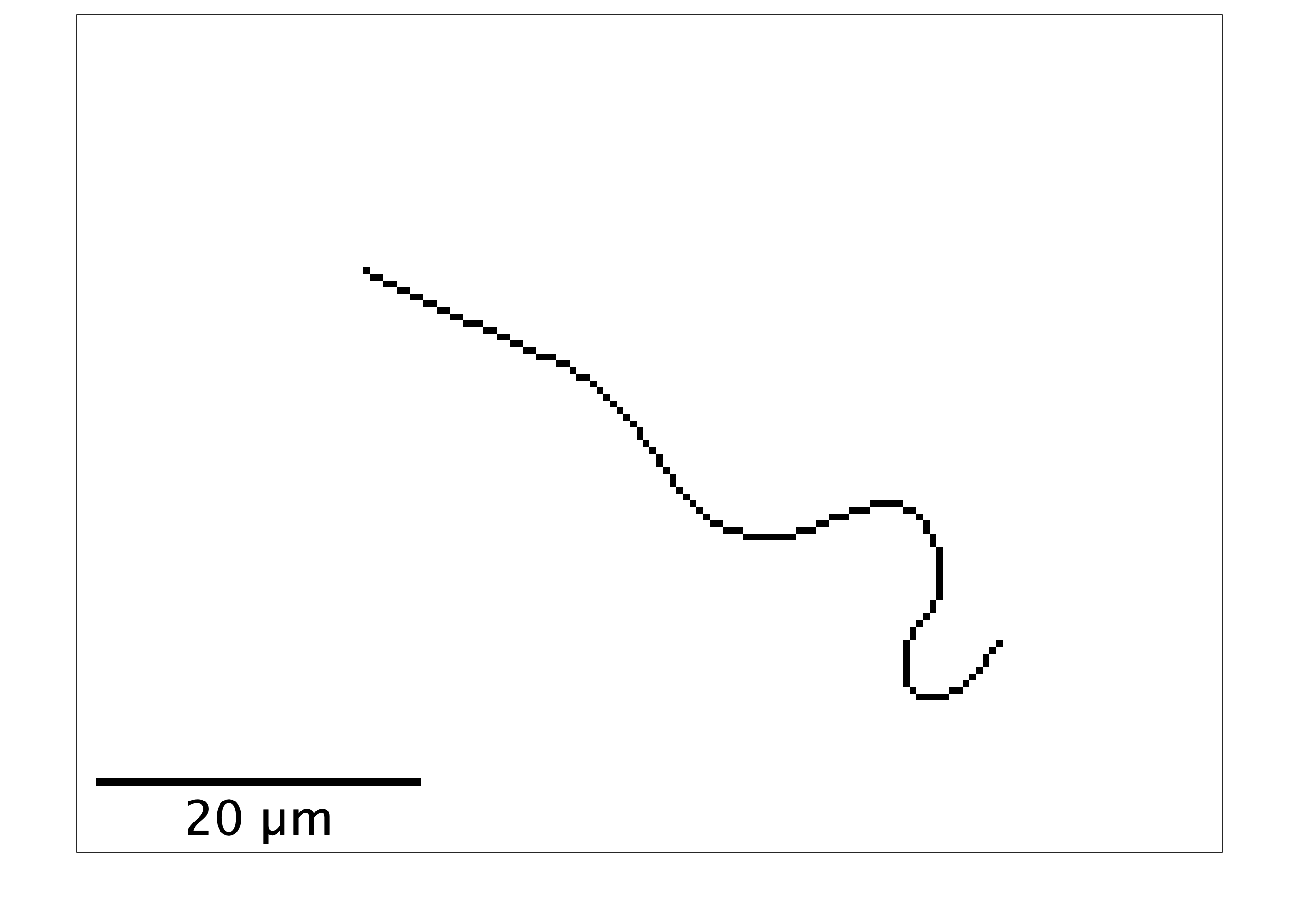

 
figure
imshow( imread('flag.tif') ,[0 255]);
axis on
set(gca,'XTick',[],'YTick',[])
box on

Fig. 1(c). Captured waveform over a single beating period. Different colours indicate different timepoints within the period.

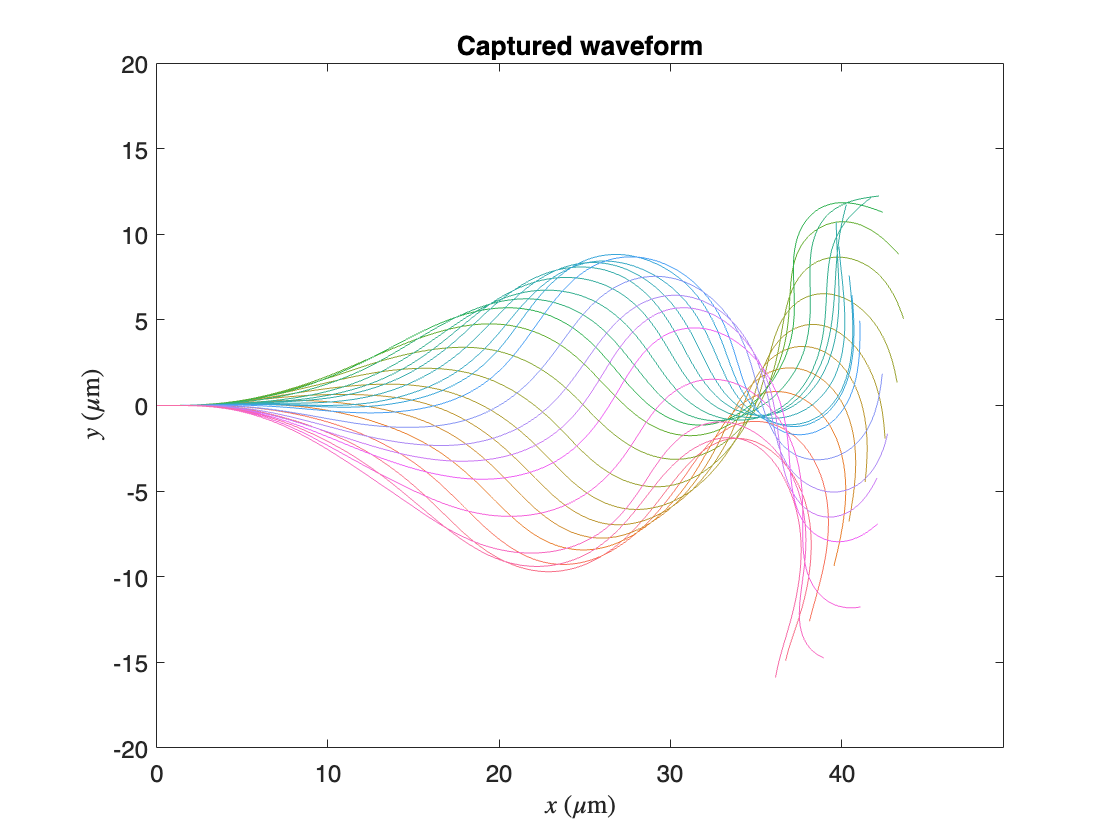

 

figure

h = plot(realBeat.xy(inds,:,1)',realBeat.xy(inds,:,2)');
set(h, {'color'}, num2cell(cc, 2));
axis equal
xlabel('$x$ ($\mu$m)','interpreter','latex')
ylabel('$y$ ($\mu$m)','interpreter','latex')
set(gca,'FontSize',12)
xlims = [0,49.457];
ylims = [-20,20];
xlim(xlims)
ylim(ylims)
set(gca,'XTick',[0 10 20 30 40])
title('Captured waveform')

Animated version of Fig. 1(c). Captured waveform (thick black line) during one beating period. Light grey shows the waveform at all the timepoints during a period.

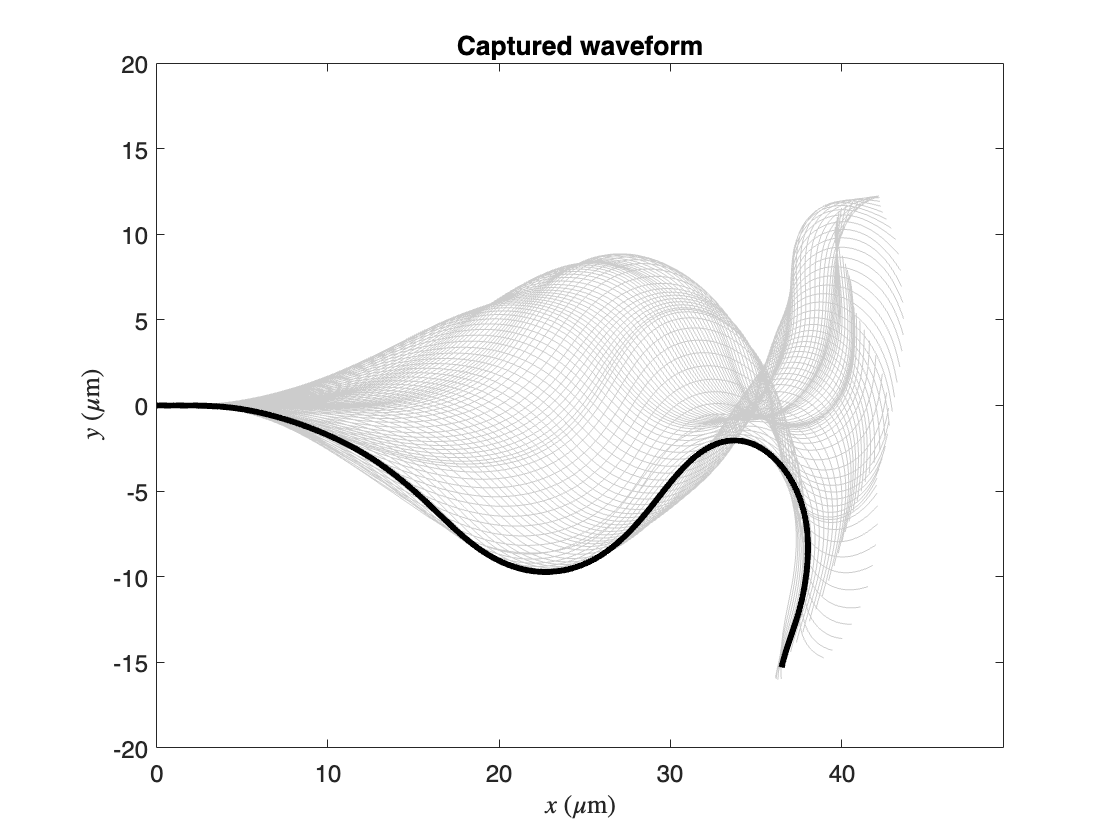

 

figure
for timepoint=1:100
    clf
    plot(realBeat.xy(:,:,1)',realBeat.xy(:,:,2)','color','#cccccc')
    hold on
    plot(realBeat.xy(timepoint,:,1)',realBeat.xy(timepoint,:,2)','color','k','LineWidth',3)
    axis equal
    xlabel('$x$ ($\mu$m)','interpreter','latex')
    ylabel('$y$ ($\mu$m)','interpreter','latex')
    set(gca,'FontSize',12)
    xlims = [0,49.457];
    ylims = [-20,20];
    xlim(xlims)
    ylim(ylims)
    set(gca,'XTick',[0 10 20 30 40])
    title('Captured waveform')
    drawnow
end

Explore the dataset from [the paper]. Select a Sperm ID (from 1 to 216). Captured waveform (thick black line) during one beating period. Light grey shows the waveform at all the timepoints during a period.

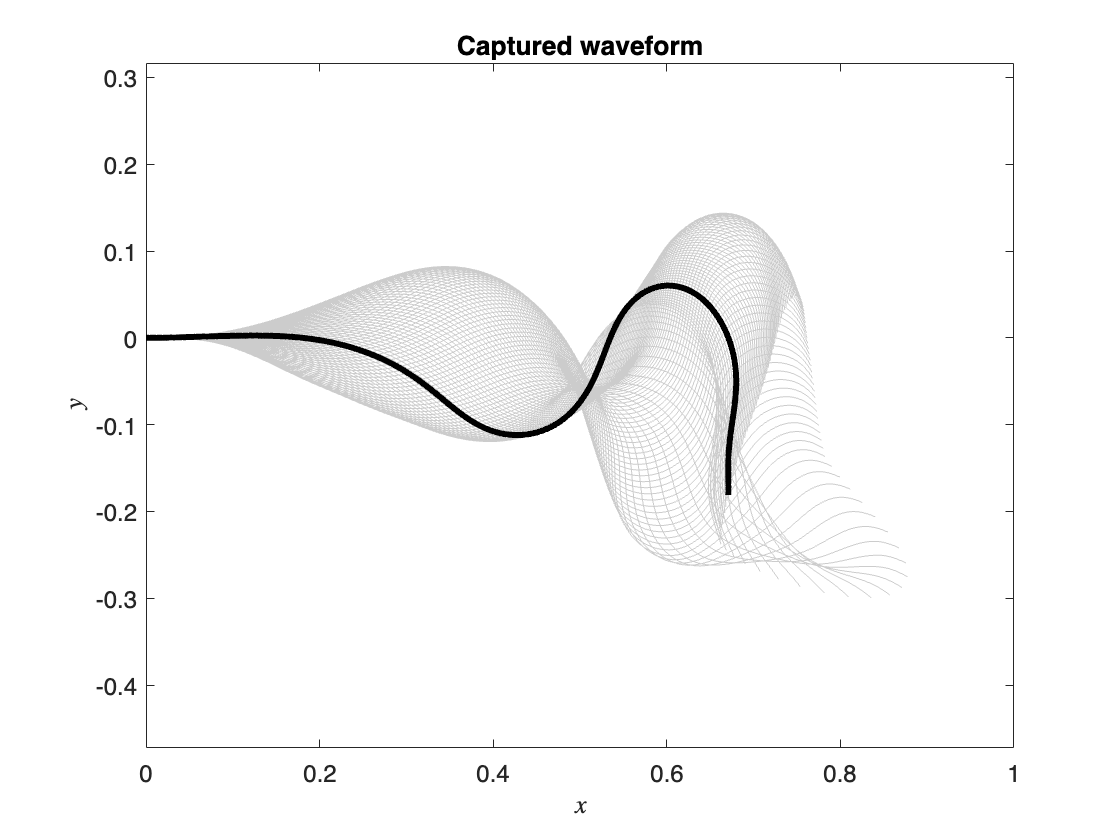

 
swimmerNumber=98;
figure
for timepoint=1:100
    clf
    plot(data{swimmerNumber}.cartesian(:,:,1)',data{swimmerNumber}.cartesian(:,:,2)','color','#cccccc')
    hold on
    plot(data{swimmerNumber}.cartesian(timepoint,:,1)',data{swimmerNumber}.cartesian(timepoint,:,2)','LineWidth',3,'Color','k')
    axis equal
    xlabel('$x$','interpreter','latex')
    ylabel('$y$','interpreter','latex')
    set(gca,'FontSize',12)
    xlim([0 1])
    set(gca,'XTick',[0 0.2 0.4 0.6 0.8 1])
    title('Captured waveform')
    drawnow
end

Compare sperm waveforms. Input a list of sperm IDs (between 1 and 216), separated by commas. For example: 1,29,167,201 

Then click Run to see them beat over one period.

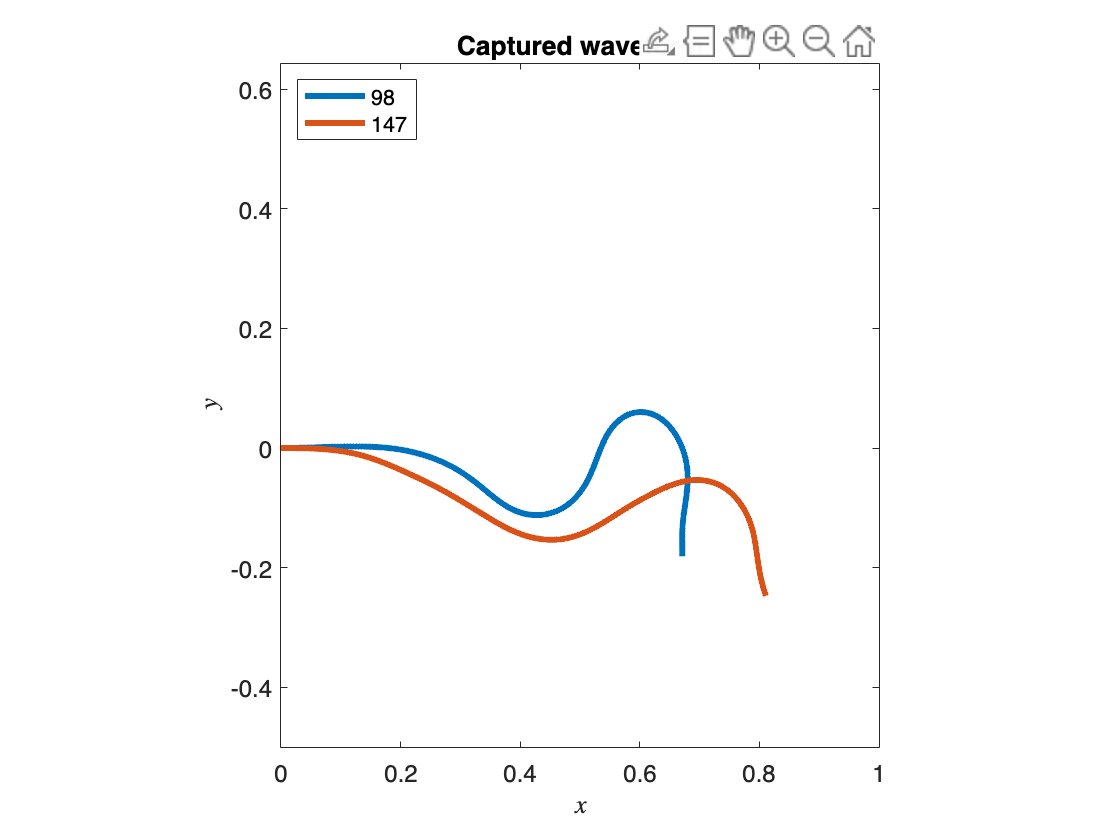

swimmerNumbersInput = "98,147";
  
try
    swimmerNumbers = str2num(swimmerNumbersInput);   
    figure
    for timepoint=1:100
        clf
        for i=swimmerNumbers
            plot(data{i}.cartesian(timepoint,:,1)',data{i}.cartesian(timepoint,:,2)','LineWidth',3)
            hold on
            axis equal
            xlabel('$x$','interpreter','latex')
            ylabel('$y$','interpreter','latex')
            set(gca,'FontSize',12)
            xlim([0 1])
            ylim([waveformMiny,waveformMaxy])
            set(gca,'XTick',[0 0.2 0.4 0.6 0.8 1])
            title('Captured waveform')
            end
        legend(string(swimmerNumbers),'location','northwest')
        drawnow
    end
catch
    warning('Please make sure that the input is a list of sperm IDs (whole numbers between 1 and 216), separated by commas. For example: 1,29,167,201')
end

Watch one sperm cell swim. Select a Sperm ID (from 1 to 216). 

% swim2 function output:
%[ --- x swimmer position -----------;
% ----y swimmer position-------------;
% ----swimmer orientation angle----;
% ----time from 0 to T_end-----------]

% swim2 waveform
% first index gives time, second index gives material point, third index
% gives x or y coordinate

phiEllipse = linspace(0,2*pi,20);
coordEllipse = [-5+(10/2)*cos(phiEllipse); (5/2)*sin(phiEllipse)];

swimmerNumber=147;
T_end=10;
 

[swim2_output_one, swim2_waveform_one] = swim2(swimmerNumber,T_end);

ans = 1

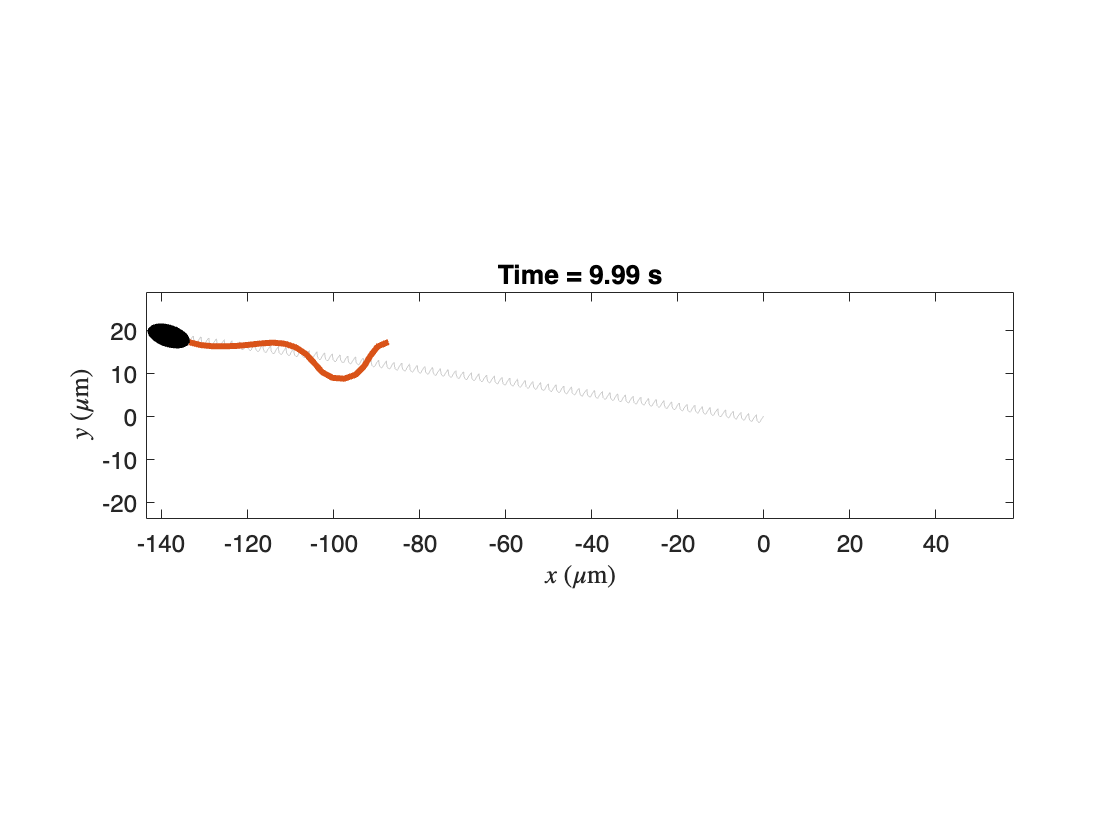

% a row for each time
swimmerEllipseOne = cell(size(swim2_output_one,2),1);


xlims = [min(min(swim2_waveform_one(:,:,1)))-10, max(max(swim2_waveform_one(:,:,1)))+10];
ylims = [min(min(swim2_waveform_one(:,:,2)))-10, max(max(swim2_waveform_one(:,:,2)))+10];

for timeIndex=1:size(swim2_output_one,2)
    thetaOne = swim2_output_one(3,timeIndex);
    rotMatOne = [cos(thetaOne), -sin(thetaOne); sin(thetaOne), cos(thetaOne)];
    swimmerEllipseOne{timeIndex} = [swim2_output_one(1,timeIndex); swim2_output_one(2,timeIndex)] + rotMatOne * coordEllipse;
end

figure
for timeIndex=1:10:size(swim2_output_one,2)
    clf
    plot(swim2_output_one(1,1:timeIndex),swim2_output_one(2,1:timeIndex),'color','#cccccc','HandleVisibility','off')
    hold on
    plot(swim2_waveform_one(timeIndex,1:50:end,1),swim2_waveform_one(timeIndex,1:50:end,2),'LineWidth',3)
    hold on
    fill(swimmerEllipseOne{timeIndex}(1,:),swimmerEllipseOne{timeIndex}(2,:),'k')
    hold on
    axis equal
    xlabel('$x$ ($\mu$m)','interpreter','latex')
    ylabel('$y$ ($\mu$m)','interpreter','latex')
    xlim(xlims)
    ylim(ylims)
    set(gca,'FontSize',12)
    title(['Time = ', num2str(swim2_output_one(4,timeIndex),'%.2f'), ' s'])
    drawnow
end

Swimmer race for long time - include sperm head and waveform.

ans = 1

ans = 1

ans = 1

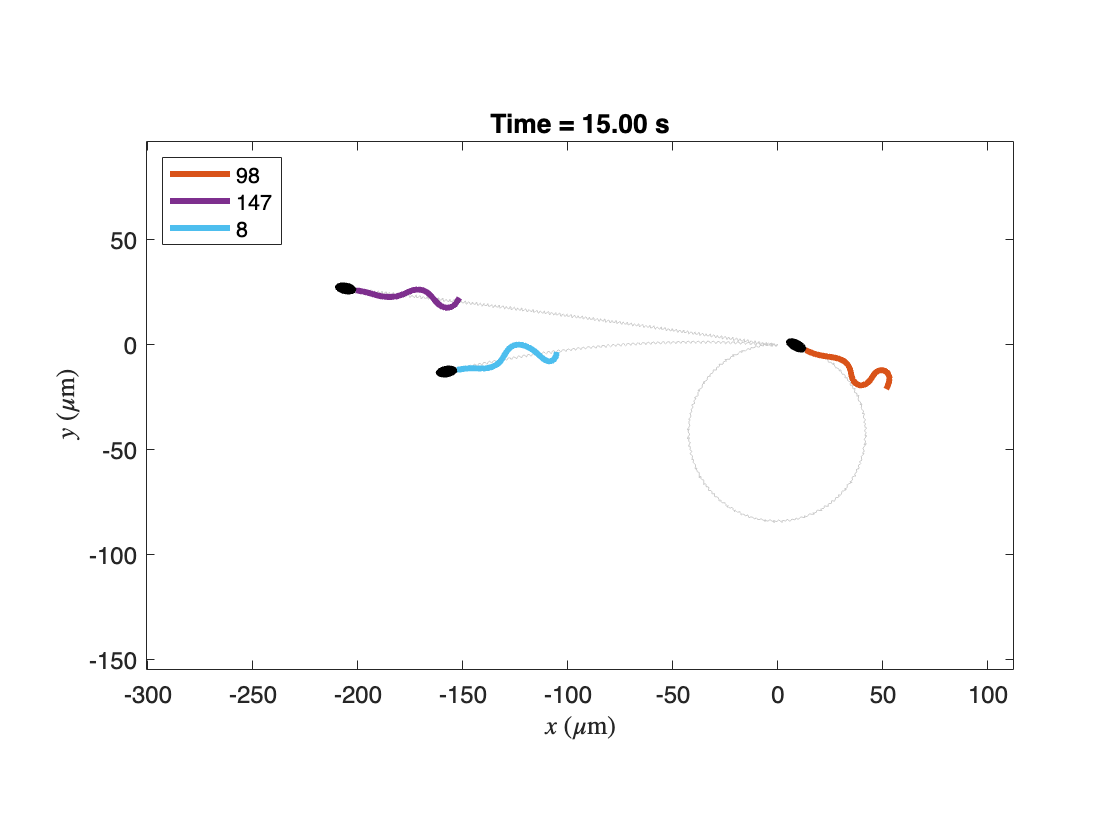

% need to fix the interpolation

% swim2 function output:
%[ --- x swimmer position -----------;
% ----y swimmer position-------------;
% ----swimmer orientation angle----;
% ----time from 0 to T_end-----------]

% swim2 waveform
% first index gives time, second index gives material point, third index
% gives x or y coordinate

% if it's too slow, consider just computing all the data for some swimmers
% and saving and loading.

phiEllipse = linspace(0,2*pi,100);
coordEllipse = [-5+(10/2)*cos(phiEllipse); (5/2)*sin(phiEllipse)];

swimmerNumbersInput = "98,147,8";
T_end=15;
 
% uncomment try catch for user-friendly
try
    swimmerNumbers = str2num(swimmerNumbersInput);    

    swimDataRaw = cell(1,length(swimmerNumbers));

    swimDataxq = cell(1,length(swimmerNumbers));
    swimDatayq = cell(1,length(swimmerNumbers));
    swimDatathetaq = cell(1,length(swimmerNumbers));

    timeq = linspace(0,T_end,T_end*20);

    swimmerEllipse = cell(length(timeq),length(swimmerNumbers));

    swimmerWaveformxq = cell(1,length(swimmerNumbers));
    swimmerWaveformyq = cell(1,length(swimmerNumbers));

    for i=1:length(swimmerNumbers)
        [swim2_output, swim2_waveform] = swim2(swimmerNumbers(i),T_end);
        swimDataRaw{i} = swim2_output;
        
        % look at x, y, theta as a function of time
        xF = griddedInterpolant(swimDataRaw{i}(4,:),swimDataRaw{i}(1,:));
        swimDataxq{i} = xF(timeq);
        yF = griddedInterpolant(swimDataRaw{i}(4,:),swimDataRaw{i}(2,:));
        swimDatayq{i} = yF(timeq);
        thetaF = griddedInterpolant(swimDataRaw{i}(4,:),swimDataRaw{i}(3,:));
        swimDatathetaq{i} = thetaF(timeq);
        
        for timeqIndex=1:length(timeq)
            theta = swimDatathetaq{i}(timeqIndex);
            rotMat = [cos(theta), -sin(theta); sin(theta), cos(theta)];
            swimmerEllipse{timeqIndex,i} = [swimDataxq{i}(timeqIndex); swimDatayq{i}(timeqIndex)] + rotMat * coordEllipse;
        end
        
        % now want to interpolate waveform in time too. x is a function of
        % material point and time. interpolate 2D scattered data... but
        % only want to interpolate in time, so use same query material points as original.

        matptIndex = 1:size(swim2_waveform,2);
        time = swim2_output(4,:);
        xSwimmer = swim2_waveform(:,:,1);
        xWaveformF = griddedInterpolant({time,matptIndex},xSwimmer);
        matptIndexq = matptIndex;
        swimmerWaveformxq{i} = xWaveformF({timeq,matptIndexq});

        ySwimmer = swim2_waveform(:,:,2);
        yWaveformF = griddedInterpolant({time,matptIndex},ySwimmer);
        swimmerWaveformyq{i} = yWaveformF({timeq,matptIndexq});

    end
    
    xlims = [min([swimDataxq{:}]) - 100, max([swimDataxq{:}]) + 70];
    ylims = [min([swimDatayq{:}]) - 70, max([swimDatayq{:}]) + 70];

    figure

    for timeqIndex=1:length(timeq)
        clf
        for i=1:length(swimmerNumbers)
            % trajectory
            plot(swimDataxq{i}(1:timeqIndex),swimDatayq{i}(1:timeqIndex),'color','#cccccc','HandleVisibility','off')
            % h=plot(swimDataxq{i}(1:timeqIndex),swimDatayq{i}(1:timeqIndex),'HandleVisibility','off');
            hold on
            % head
            fill(swimmerEllipse{timeqIndex,i}(1,:),swimmerEllipse{timeqIndex,i}(2,:),'k','HandleVisibility','off')
            hold on
            % waveform
            plot(swimmerWaveformxq{i}(timeqIndex,1:10:end),swimmerWaveformyq{i}(timeqIndex,1:10:end),'LineWidth',3)
            % plot(swimmerWaveformxq{i}(timeqIndex,1:10:end),swimmerWaveformyq{i}(timeqIndex,1:10:end),'LineWidth',3,'color',h.Color)
            axis equal
            xlabel('$x$ ($\mu$m)','interpreter','latex')
            ylabel('$y$ ($\mu$m)','interpreter','latex')
            set(gca,'FontSize',12)
            xlim(xlims)
            ylim(ylims)
            title(['Time = ', num2str(timeq(timeqIndex),'%.2f'), ' s'])
        end
        legend(string(swimmerNumbers),'location','northwest')
        drawnow
    end
catch
    warning('Something has not worked as expected. Please make sure that the input is a list of sperm IDs (whole numbers between 1 and 216), separated by commas. For example: 11,78,157')
end

Fig. 1(d). Synthetic waveform over a single beat period. Different colours indicate different timepoints within the period.

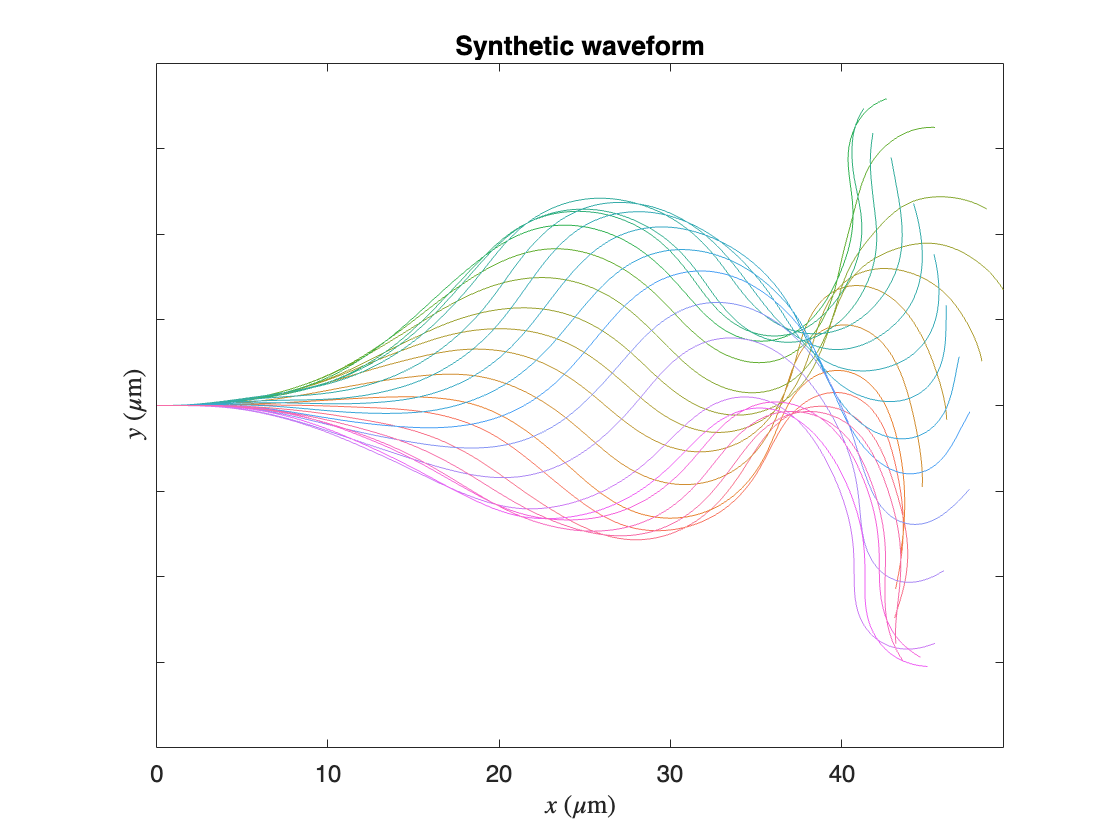

 


figure
h = plot(syntheticBeat.xy(inds,:,1)',syntheticBeat.xy(inds,:,2)');
set(h, {'color'}, num2cell(cc, 2));
axis equal
xlabel('$x$ ($\mu$m)','interpreter','latex')
ylabel('$y$ ($\mu$m)','interpreter','latex')
set(gca,'FontSize',12,'YTickLabel',{})
xlims = [0,49.457];
ylims = [-20,20];
xlim(xlims)
ylim(ylims)
set(gca,'XTick',[0 10 20 30 40])
title('Synthetic waveform')

Animated version of Fig. 1(d). Captured waveform (thick black line) during one beating period. Light grey shows the waveform at all the timepoints during a period.

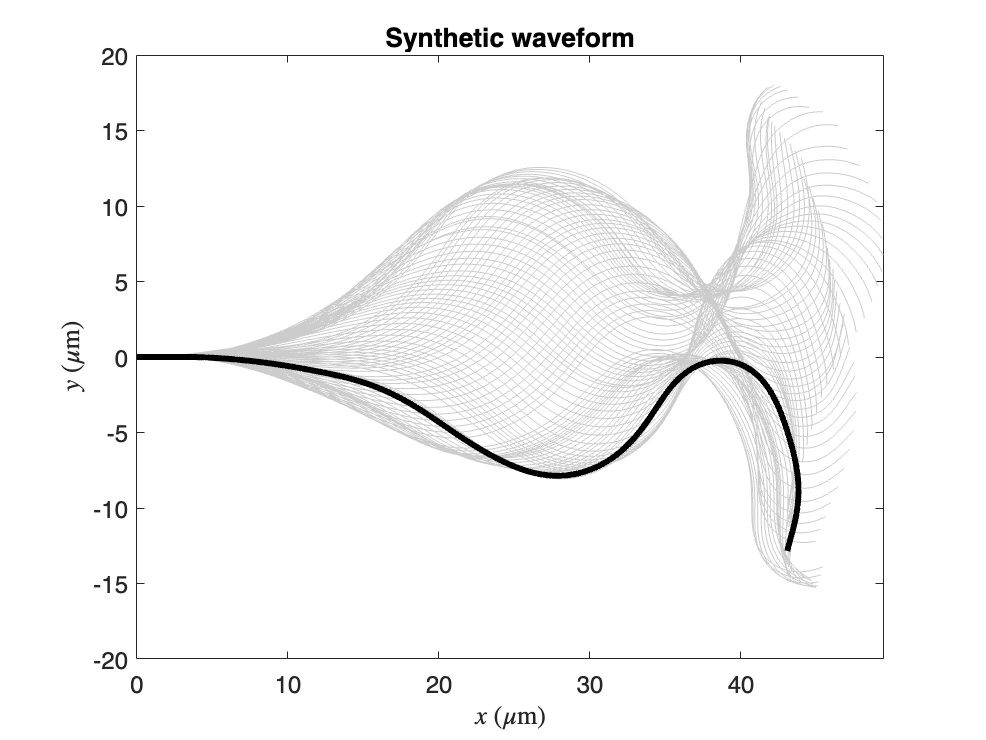


 

figure
for timepoint=1:100
    clf
    % grey
    plot(syntheticBeat.xy(:,:,1)',syntheticBeat.xy(:,:,2)','color','#cccccc')
    hold on
    plot(syntheticBeat.xy(timepoint,:,1)',syntheticBeat.xy(timepoint,:,2)','color','k','LineWidth',3)
    axis equal
    xlabel('$x$ ($\mu$m)','interpreter','latex')
    ylabel('$y$ ($\mu$m)','interpreter','latex')
    set(gca,'FontSize',12)
    xlims = [0,49.457];
    ylims = [-20,20];
    xlim(xlims)
    ylim(ylims)
    set(gca,'XTick',[0 10 20 30 40])
    title('Synthetic waveform')
    drawnow
end


Generate synthetic waveforms. We sample a synthetic waveform using a method that has the same mean and variance as the empirical waveform distribution.

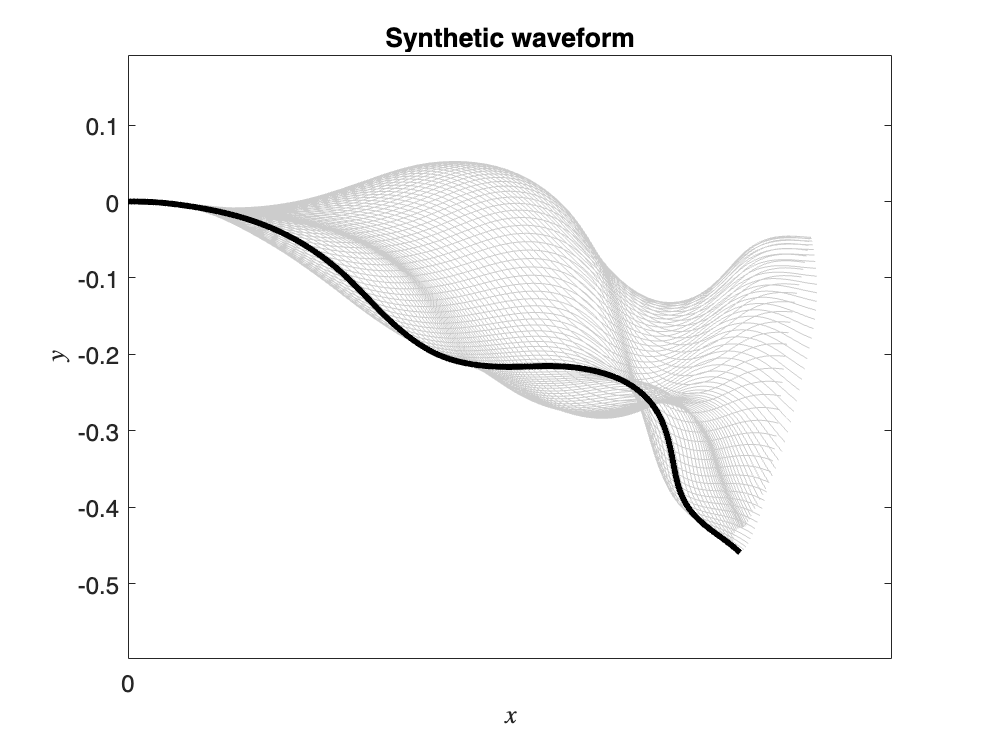

 
randomSynthBeat = synthetic_beat(data);

figure
for timepoint=1:100
    clf
    plot(randomSynthBeat.cartesian(:,:,1)',randomSynthBeat.cartesian(:,:,2)','color','#cccccc')
    hold on
    plot(randomSynthBeat.cartesian(timepoint,:,1)',randomSynthBeat.cartesian(timepoint,:,2)','color','k','LineWidth',3)
    axis equal
    xlabel('$x$','interpreter','latex')
    ylabel('$y$','interpreter','latex')
    set(gca,'FontSize',12)
    xlim([0 1])
    set(gca,'XTick',[0 10 20 30 40])
    title('Synthetic waveform')
    drawnow
end